% define variáveis simbólicas
syms t V0 R C real
syms v(t)

% derivadas
Dv = diff(v(t), t); 

% Equação diferencial ordinária
ode = C*Dv + v(t)/R == 0

$$ode = C\,\frac{\partial }{\partial t}v\left(t\right)+\frac{v\left(t\right)}{R}=0$$


% Condições iniciais
cond = v(0) == V0

$$cond = v\left(0\right)=V_{0}$$


% Matlab, resolva!
v_sol = dsolve(ode, cond)

$$v\_sol = V_{0}\,{\mathrm{e}}^{-\frac{t}{C\,R}}$$

% Vamos substituir alguns valores no resultado geral
v_sol = subs(v_sol, {V0 R C}, {10 1e6 1e-6})

$$v\_sol = 10\,{\mathrm{e}}^{-t}$$

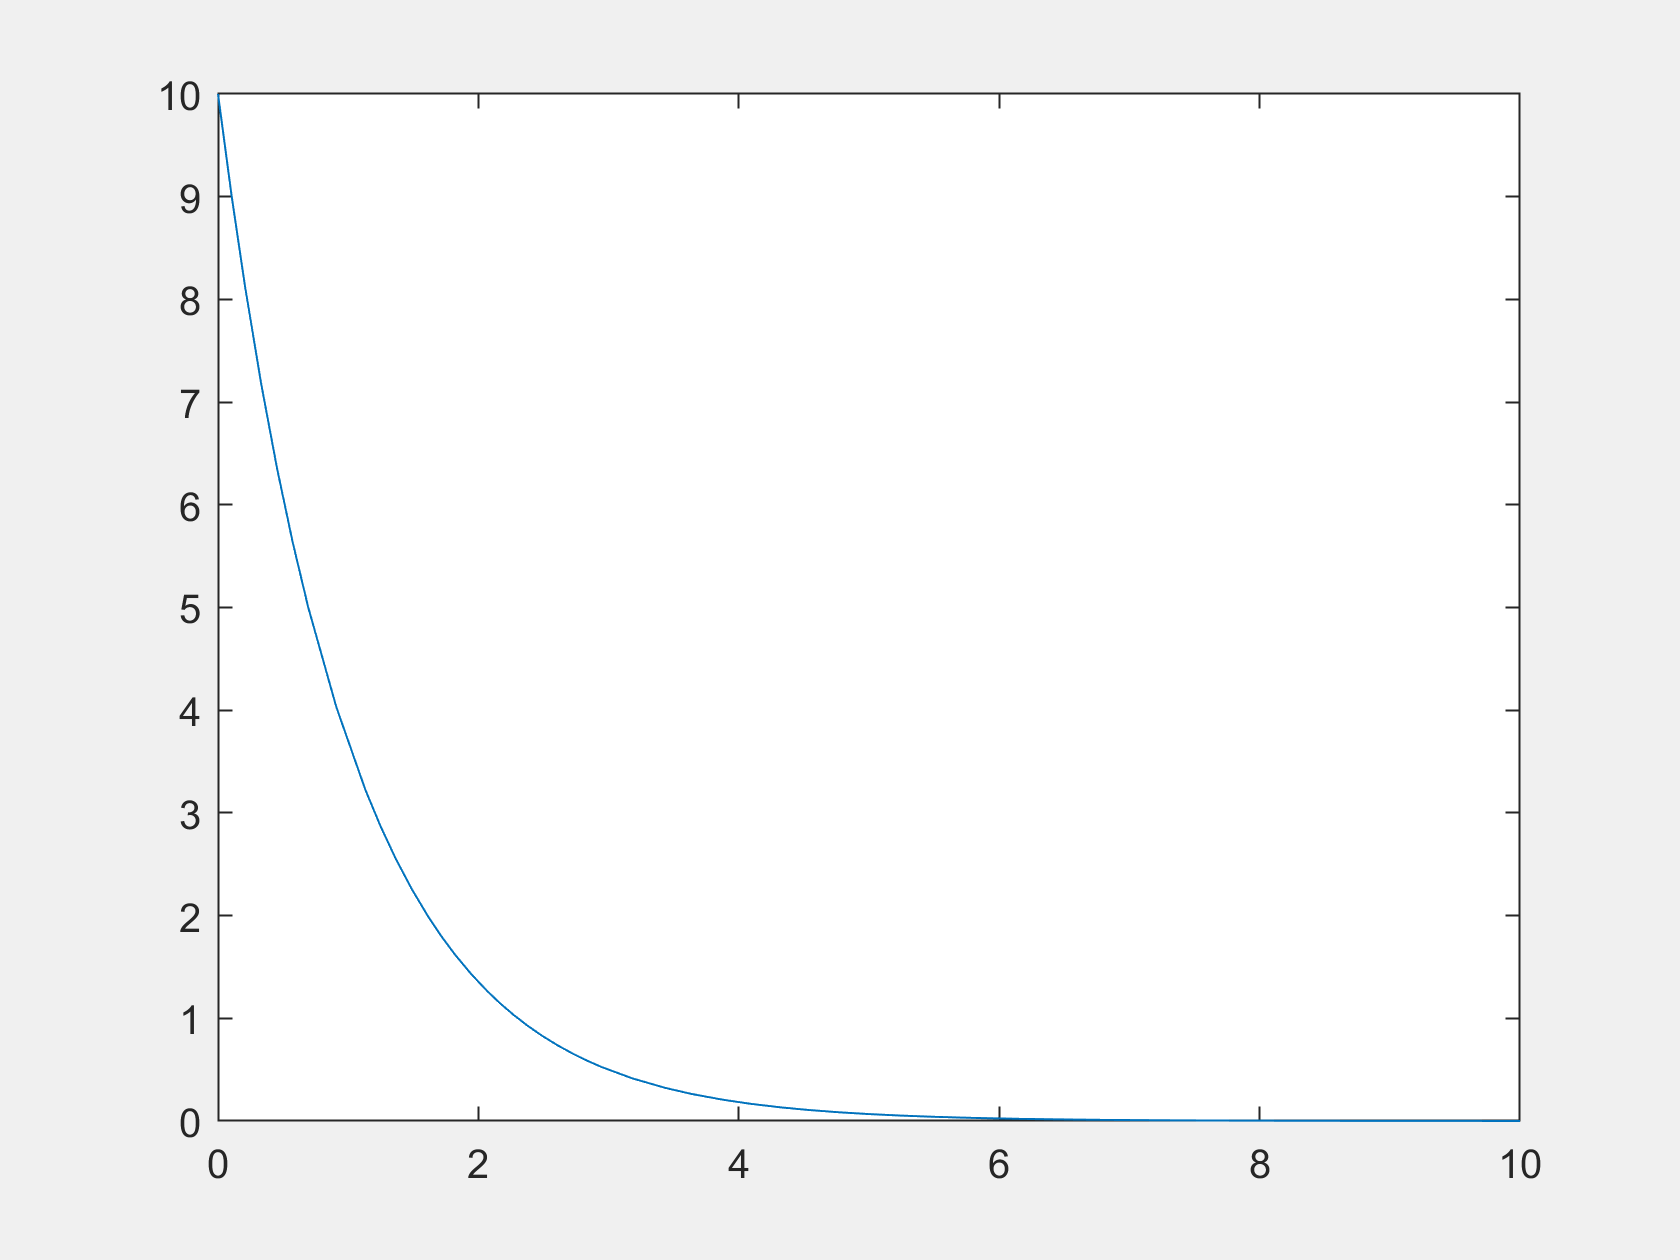

% Para plotar também em uma janela separada
set(gcf, 'Visible', 'On')
fplot(v_sol, [0 10])